## Rot_Wing control Moment definition and Automatic skew controller

### Motors modelling

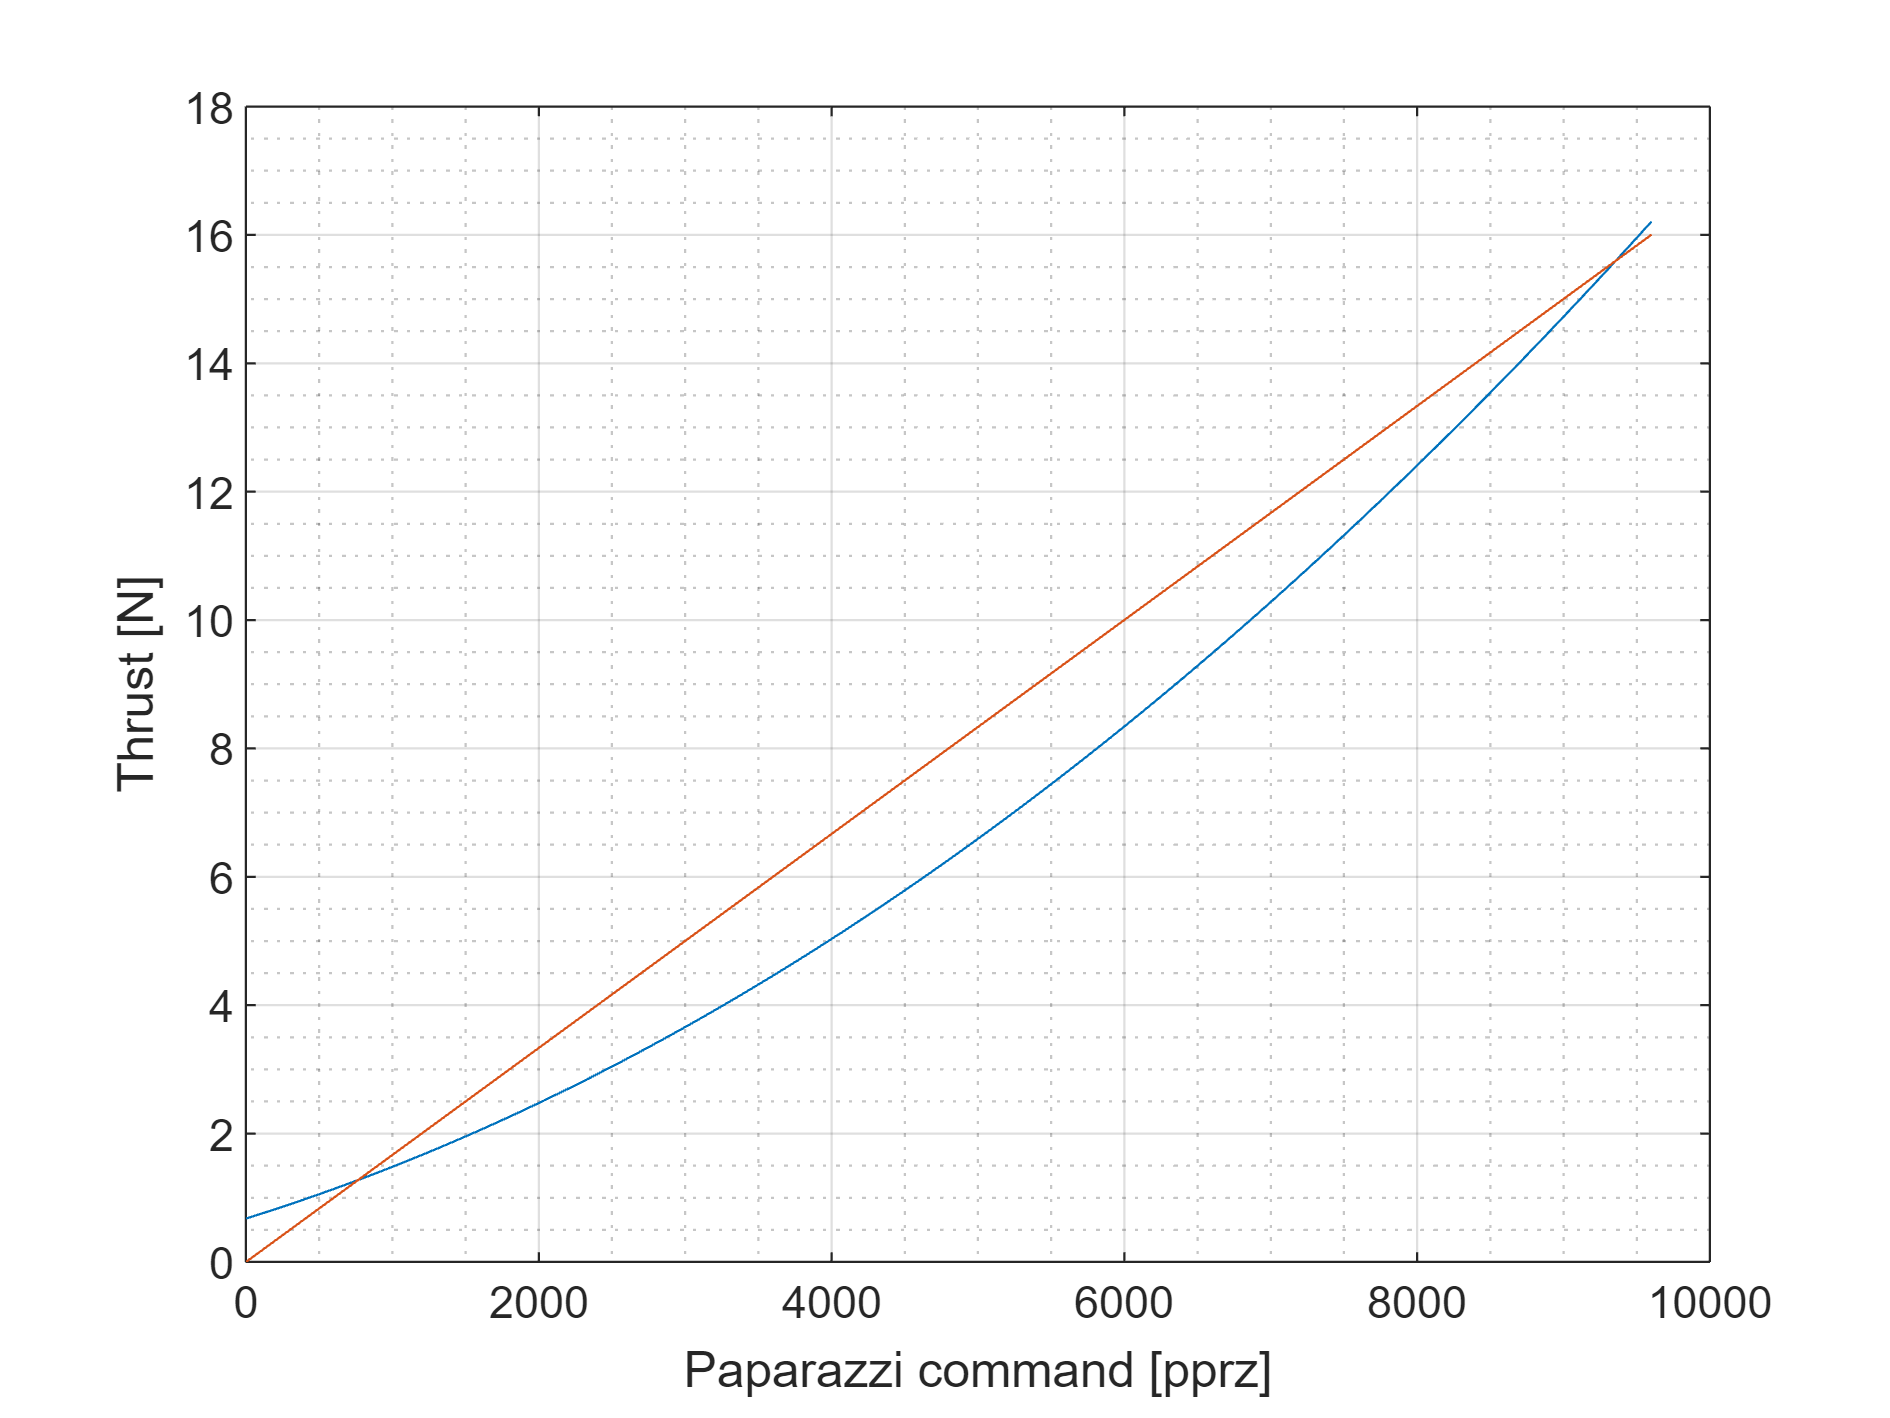

clear
pprz = linspace(0,9600);
T_f = 9.446e-8 *pprz.^2+7.11e-4*pprz+0.67632;
T_lin = 1.667e-3*pprz;
figure(1)
clf
plot(pprz,T_f)
hold on
plot(pprz,T_lin)
grid on 
grid minor
xlabel("Paparazzi command [pprz]")
ylabel("Thrust [N]")

RMSE = rms((T_f-T_lin)/T_f)

RMSE = 0.1023

The RMSE indicates an average deviation of 10%. 

Similarly, also the exerted torque can be modelled

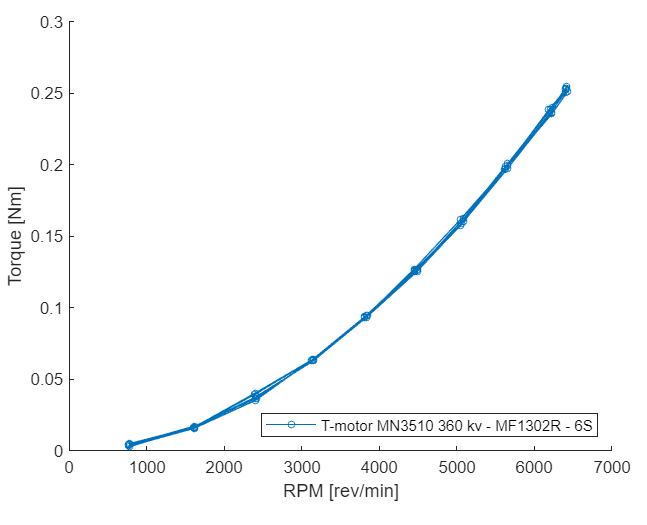

clear all
syms  b_abs T_pprz Q_pprz omega_k k_t_k k_q_k delta_mot_k
syms Lambda 'real'
syms j0 [3,1] 'real'
syms i0 [3,1] 'real'
syms omega [4,1] 'real'
syms k_t [4,1] 'real'
syms k_q [4,1] 'real'
syms b [4,1] 'real'
syms delta_mot [4,1] 'real'
syms scg [3,1] 'real'
T(k_t_k,omega_k)= k_t_k*omega_k;
Q(k_q_k,omega_k)= k_q_k*omega_k;
j(j0.',Lambda) = [cos(Lambda)*j01-sin(Lambda)*j02;sin(Lambda)*j01+cos(Lambda)*j02;j03];
b_fun(Lambda,j0.', scg.', b_abs) = j(j01, j02, j03,Lambda).*b_abs+scg;
i(i0.',j0.', delta_mot_k) = cos(delta_mot_k).*i0+sin(delta_mot_k).*cross(j(j01, j02, j03,Lambda),i0)+(1-cos(delta_mot_k)).*j(j01, j02, j03,Lambda)*(dot(j(j01, j02, j03,Lambda),i0));
M(Lambda,i0.',j0.', scg.', b_abs,delta_mot_k,T_pprz,Q_pprz)=cross(b_fun(Lambda,j01, j02, j03, scg1, scg2, scg3, b_abs),i(i01,i02,i03,j01, j02, j03, delta_mot_k).*T_pprz)+ Q_pprz * abs(i0);


The full control moment definition for the four quadrotors is then defined as :

M_mot_full(Lambda,b.',k_t.',k_q.',omega.') = simplify( ...
  [ M(0,0,0,-1,1, 0, 0, scg1, scg2, scg3, b1,delta_mot1,T(k_t1,omega1),Q(k_q1,omega1)), ...
    M(Lambda,0,0,-1,0, 1, 0, scg1, scg2, scg3, b2,delta_mot2,T(k_t2,omega2),Q(k_q2,-omega2)), ...
    M(0,0,0,-1,-1, 0, 0, scg1, scg2, scg3, b3,delta_mot3,T(k_t3,omega3),Q(k_q3,omega3)), ...
    M(Lambda,0,0,-1,0, -1, 0, scg1, scg2, scg3, b4,delta_mot4,T(k_t4,omega4),Q(k_q4,-omega4))]);
disp(simplifyFraction(M_mot_full./(ones(3,4).*[omega1,omega2,omega3,omega4])))

The reduced form for cg=rp and no motor twist is:

M_mot(Lambda,b.',k_t.',k_q.',omega.')  = simplify( ...
  [ M(0,0,0,-1,1, 0, 0, 0, 0, 0, b1,0,T(k_t1,omega1),Q(k_q1,omega1)), ...
    M(Lambda,0,0,-1,0, 1, 0, 0, 0, 0, b2,0,T(k_t2,omega2),Q(k_q2,-omega2)), ...
    M(0,0,0,-1,-1, 0, 0, 0, 0, 0, b3,0,T(k_t3,omega3),Q(k_q3,omega3)), ...
    M(Lambda,0,0,-1,0, -1, 0, 0, 0, 0, b4,0,T(k_t4,omega4),Q(k_q4,-omega4))]);
G_mot(Lambda,b.',k_t.',k_q.') = simplifyFraction(M_mot./(ones(3,4).*[omega1,omega2,omega3,omega4]))

$$G\_mot(Lambda, b1, b2, b3, b4, k\_t1, k\_t2, k\_t3, k\_t4, k\_q1, k\_q2, k\_q3, k\_q4) = \left(\begin{array}{cccc} 0 & -b_{2}\,k_{\mathrm{t2}}\,\cos\left(\Lambda \right) & 0 & b_{4}\,k_{\mathrm{t4}}\,\cos\left(\Lambda \right)\\ b_{1}\,k_{\mathrm{t1}} & -b_{2}\,k_{\mathrm{t2}}\,\sin\left(\Lambda \right) & -b_{3}\,k_{\mathrm{t3}} & b_{4}\,k_{\mathrm{t4}}\,\sin\left(\Lambda \right)\\ k_{\mathrm{q1}} & -k_{\mathrm{q2}} & k_{\mathrm{q3}} & -k_{\mathrm{q4}} \end{array}\right)$$

### Aerodynamic Surfaces Modelling

syms b_al b_el b_ru Lal Lar Lel Lru k_surf k_al k_ar k_el k_ru delta_as delta_al delta_ar delta_el delta_ru v k_al_q k_al_p k_ar_q k_ar_p 
L_as(k_surf,delta_as,v,Lambda)= k_surf*delta_as*(sin(Lambda)*v)^2

$$L\_as(k\_surf, delta\_as, v, Lambda) = \delta_{\mathrm{as}}\,k_{\mathrm{surf}}\,v^{2}\,{\sin\left(\Lambda \right)}^{2}$$

M_aero(Lambda,b_al,b_el,b_ru,k_al,k_ar,k_el,k_ru,delta_al,delta_ar,delta_el,delta_ru,v)=simplify( ...
  [ M(Lambda,0,0,-1,-1, 0, 0, 0, 0, 0, b_al,deg2rad(0),L_as(k_al,delta_al,v,Lambda),0), ...
    M(Lambda,0,0,-1,1, 0, 0, 0, 0, 0, b_al,deg2rad(0),L_as(k_ar,delta_ar,v,Lambda),0), ...
    M(0,0,0,-1,-1, 0, 0, 0, 0, 0, b_el,deg2rad(0),L_as(k_el,delta_el,v,pi/2),0), ...
    M(0,0,1,0,-1, 0, 0, 0, 0, 0, b_ru,deg2rad(0),L_as(k_ru,delta_ru,v,pi/2),0)]);
G_as(Lambda,b_al,b_el,b_ru,k_al,k_ar,k_el,k_ru,v) = M_aero./(ones(3,4).*[delta_al,delta_ar,delta_el,delta_ru])

$$G\_as(Lambda, b\_al, b\_el, b\_ru, k\_al, k\_ar, k\_el, k\_ru, v) = \begin{array}{l} \left(\begin{array}{cccc} b_{\mathrm{al}}\,k_{\mathrm{al}}\,v^{2}\,{\sin\left(\Lambda \right)}^{3} & -b_{\mathrm{al}}\,k_{\mathrm{ar}}\,v^{2}\,{\sin\left(\Lambda \right)}^{3} & 0 & 0\\ -b_{\mathrm{al}}\,k_{\mathrm{al}}\,v^{2}\,\sigma_{1} & b_{\mathrm{al}}\,k_{\mathrm{ar}}\,v^{2}\,\sigma_{1} & -b_{\mathrm{el}}\,k_{\mathrm{el}}\,v^{2} & 0\\ 0 & 0 & 0 & -b_{\mathrm{ru}}\,k_{\mathrm{ru}}\,v^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\Lambda \right)-{\cos\left(\Lambda \right)}^{3} \end{array}$$

### Conclusion

M_c_tot(Lambda,b1,b2,b3,b4,k_t_k,k_q_k,omega1,omega2,omega3,omega4,b_al,b_el,b_ru,k_al,k_ar,k_el,k_ru,delta_al,delta_ar,delta_el,delta_ru,v) = sum(M_mot(Lambda,b1,b2,b3,b4,k_t1, k_t2, k_t3, k_t4, k_q1, k_q2, k_q3, k_q4,omega1,omega2,omega3,omega4) + M_aero(Lambda,b_al,b_el,b_ru,k_al,k_ar,k_el,k_ru,delta_al,delta_ar,delta_el,delta_ru,v),2)

$$\begin{array}{l} \left(\begin{array}{c} b_{4}\,k_{\mathrm{t4}}\,\omega_{4}\,\cos\left(\Lambda \right)-b_{2}\,k_{\mathrm{t2}}\,\omega_{2}\,\cos\left(\Lambda \right)+b_{\mathrm{al}}\,\delta_{\mathrm{al}}\,k_{\mathrm{al}}\,v^{2}\,{\sin\left(\Lambda \right)}^{3}-b_{\mathrm{al}}\,\delta_{\mathrm{ar}}\,k_{\mathrm{ar}}\,v^{2}\,{\sin\left(\Lambda \right)}^{3}\\ b_{1}\,k_{\mathrm{t1}}\,\omega_{1}-b_{3}\,k_{\mathrm{t3}}\,\omega_{3}-b_{2}\,k_{\mathrm{t2}}\,\omega_{2}\,\sin\left(\Lambda \right)+b_{4}\,k_{\mathrm{t4}}\,\omega_{4}\,\sin\left(\Lambda \right)-b_{\mathrm{el}}\,\delta_{\mathrm{el}}\,k_{\mathrm{el}}\,v^{2}-b_{\mathrm{al}}\,\delta_{\mathrm{al}}\,k_{\mathrm{al}}\,v^{2}\,\sigma_{1}+b_{\mathrm{al}}\,\delta_{\mathrm{ar}}\,k_{\mathrm{ar}}\,v^{2}\,\sigma_{1}\\ -b_{\mathrm{ru}}\,\delta_{\mathrm{ru}}\,k_{\mathrm{ru}}\,v^{2}+k_{\mathrm{q1}}\,\omega_{1}-k_{\mathrm{q2}}\,\omega_{2}+k_{\mathrm{q3}}\,\omega_{3}-k_{\mathrm{q4}}\,\omega_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\Lambda \right)-{\cos\left(\Lambda \right)}^{3} \end{array}$$


$$M_c =\left(\begin{array}{cccc}
0 & -b_2 \,k_{\textrm{t2}} \,\cos \left(\Lambda \right) & 0 & b_4 \,k_{\textrm{t4}} \,\cos \left(\Lambda \right)\\
b_1 \,k_{\textrm{t1}}  & -b_2 \,k_{\textrm{t2}} \,\sin \left(\Lambda \right) & -b_3 \,k_{\textrm{t3}}  & b_4 \,k_{\textrm{t4}} \,\sin \left(\Lambda \right)\\
k_{\textrm{q1}}  & -k_{\textrm{q2}}  & k_{\textrm{q3}}  & -k_{\textrm{q4}} 
\end{array}\right)\left\lbrack \begin{array}{c}
\omega_1 \\
\omega_2 \\
\omega_3 \\
\omega_4 
\end{array}\right\rbrack +\left(\begin{array}{cccc}
b_{\textrm{al}} \,k_{\textrm{al}} \,v^2 \,{\sin \left(\Lambda \right)}^3  & -b_{\textrm{al}} \,k_{\textrm{ar}} \,v^2 \,{\sin \left(\Lambda \right)}^3  & 0 & 0\\
-b_{\textrm{al}} \,k_{\textrm{al}} \,v^2 \,{\left(\cos \left(\Lambda \right)-{\cos \left(\Lambda \right)}^3 \right)} & b_{\textrm{al}} \,k_{\textrm{ar}} \,v^2 \,{\left(\cos \left(\Lambda \right)-{\cos \left(\Lambda \right)}^3 \right)} & -b_{\textrm{el}} \,k_{\textrm{el}} \,v^2  & 0\\
0 & 0 & 0 & -b_{\textrm{ru}} \,k_{\textrm{ru}} \,v^2 
\end{array}\right)\left\lbrack \begin{array}{c}
\delta_{\textrm{al}} \\
\delta_{\textrm{ar}} \\
\delta_{\textrm{el}} \\
\delta_{\textrm{ru}} 
\end{array}\right\rbrack$$


### Test of derived Control moment Matrix

Physical Quantities of drone

mass = 3.5;      %[kg]
g    = 9.81;     %[m/s^2] 
b_mot  = [0.345,0.345,0.345,0.345];    %[m]
b_as = [0.65,0.65,0.665,0.665];

Aero Qualities of wing 

cl_max = 1.3;  % [-]                          
S_wing = 1.56 * 0.235; % [m^2]
rho = 1.225; % [kg/m^3]
pitch_q = deg2rad(10);
lift(Lambda,v)= -0.5*rho*S_wing*v^2*([-1.8847,-0.2780,-1.5037,-0.0043]*[pitch_q*sin(Lambda)^2,sin(Lambda)^2,pitch_q,1].');
Thrust(Lambda,v) = max(mass*g - lift(Lambda,v),0); %[N]
thrust_level = matlabFunction(Thrust);

Motor Characteristics 

u_lim_mot = [0 9600];
k_mot = [1.667e-3,1.667e-3,1.667e-3,1.667e-3];
k_torq_mot = [2.604e-5,2.604e-5,2.604e-5,2.604e-5];

Aero surf Characteristics

u_lim_as  = [-9600 9600];
k_as = [9.06331934128222e-07,1.10968762904728e-06,-1.88703133081111e-06,4.37392528231564e-07]

k_as = 1.0e-05 *

    0.0906    0.1110   -0.1887    0.0437


Query points

points = 30;
lambda_q = linspace(0,pi()/2,points);
v_q = linspace (0,18,points);
[L,V] = meshgrid(lambda_q,v_q);

Evaluation of control moment

M_c(Lambda,v) = [G_mot(Lambda,b_mot(1),b_mot(2),b_mot(3),b_mot(4),k_mot(1),k_mot(2),k_mot(3),k_mot(4),k_torq_mot(1),k_torq_mot(2),k_torq_mot(3),k_torq_mot(4)),G_as(Lambda,b_as(1),b_as(3),b_as(4),k_as(1),k_as(2),k_as(3),k_as(4),v)];
M_c_roll = zeros(size(L));
M_c_pitch = zeros(size(L));
M_c_yaw = zeros(size(L));
Thrust_surf = zeros(size(L));

%%%%%%% To save time you can run the pre-sets %%%%%%%%%%%%%%%%%%%
for ii = 1:size(L,1)
    for jj = 1:size(L,2)
%%%%%%% Define optimisation variables aka actuator states%%%%%%%%
        mo1 = optimvar('mo1');
        mo2 = optimvar('mo2');
        mo3 = optimvar('mo3');
        mo4 = optimvar('mo4');
        aes1 = optimvar('aes1');
        aes2 = optimvar('aes2');
        aes3 = optimvar('aes3');
        aes4 = optimvar('aes4');
        M_c_num = matlabFunction(M_c);

      % prob.Objective = Cost function of Optization problem
      % cons1          = Maximum saturation Limits
      % cons2          = Minimum saturation Limits
      % cons3          = (Thrust level + Lift) should be enough to keep the drone airborne
      % cons4 & cons 5 = Solution generates 0 moment on other axes

%%%%%%% Minimum Roll moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%        
        prob1 = optimproblem;
        f = M_c_num(L(ii,jj),V(ii,jj));                     
        opts = optimoptions("linprog",Display="none");
        prob1.Objective = f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob1.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob1.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob1.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob1.Constraints.cons4 = f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob1.Constraints.cons5 = f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol1,fval1]  = solve(prob1,Options=opts);
%%%%%%% Maximum Roll moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
        prob2 = optimproblem;
        opts = optimoptions("linprog",Display="none");
        prob2.Objective = -f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob2.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob2.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob2.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob2.Constraints.cons4 = f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob2.Constraints.cons5 = f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol2,fval2]  = solve(prob2,Options=opts);
        M_c_roll(ii,jj) = -mean([fval1,fval2]);
        Thrust_surf(ii,jj) = thrust_level(L(ii,jj),V(ii,jj));
%%%%%%% Minimum Pitch moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
        prob3 = optimproblem;
        opts = optimoptions("linprog",Display="none");
        prob3.Objective = f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob3.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob3.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob3.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob3.Constraints.cons4 = f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob3.Constraints.cons5 = f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol3,fval3]  = solve(prob3,Options=opts);
%%%%%%% Maximum Pitch moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
        prob4 = optimproblem;
        opts = optimoptions("linprog",Display="none");
        prob4.Objective = -f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob4.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob4.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob4.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob4.Constraints.cons4 = f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob4.Constraints.cons5 = f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol4,fval4]  = solve(prob4,Options=opts);
        M_c_pitch(ii,jj) = -mean([fval3,fval4]);
%%%%%%% Minimum Yaw moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
        prob5 = optimproblem;
        opts = optimoptions("linprog",Display="none");
        prob5.Objective = f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob5.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob5.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob5.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob5.Constraints.cons4 = f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob5.Constraints.cons5 = f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol5,fval5]  = solve(prob5,Options=opts);
%%%%%%% Maximum Yaw moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
        prob6 = optimproblem;
        opts = optimoptions("linprog",Display="none");
        prob6.Objective = -f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob6.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob6.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob6.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob6.Constraints.cons4 = f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob6.Constraints.cons5 = f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol6,fval6]  = solve(prob6,Options=opts);
        M_c_yaw(ii,jj) = -mean([fval5,fval6]);
    end
end

Plot the surfaces to have an idea of how the maximum control moment changes with $\Lambda$ and v.

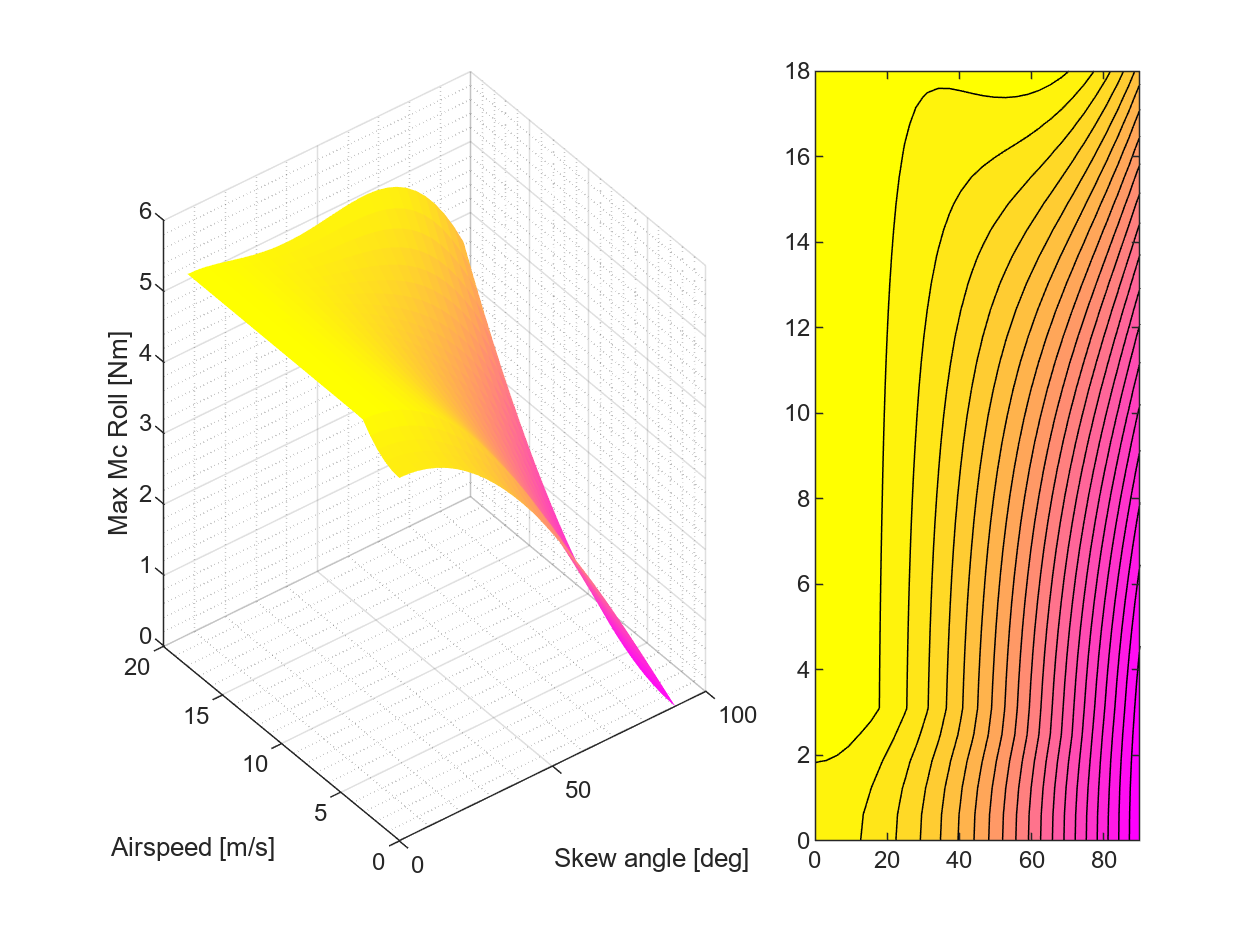

figure(10)
clf
tiledlayout(1,5);
nexttile([1,3])
s=surf(rad2deg(L),V,M_c_roll,'FaceAlpha',1.0);
s.EdgeColor = 'none';
colormap(spring)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Max Mc Roll [Nm]')
nexttile([1,2])
contourf(rad2deg(L),V,M_c_roll,20)

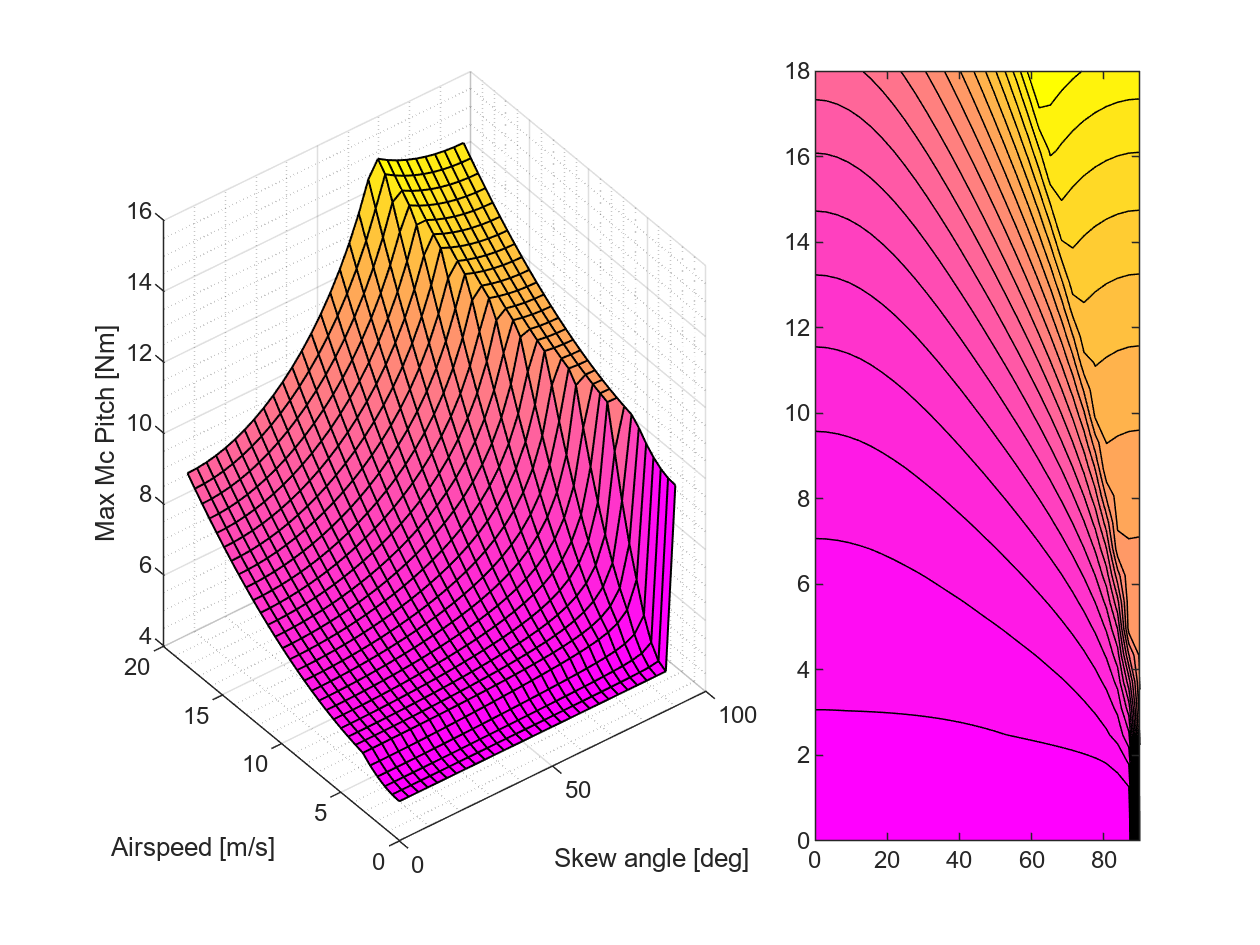

figure(11)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,M_c_pitch)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Max Mc Pitch [Nm]')
nexttile([1,2])
contourf(rad2deg(L),V,M_c_pitch,20)

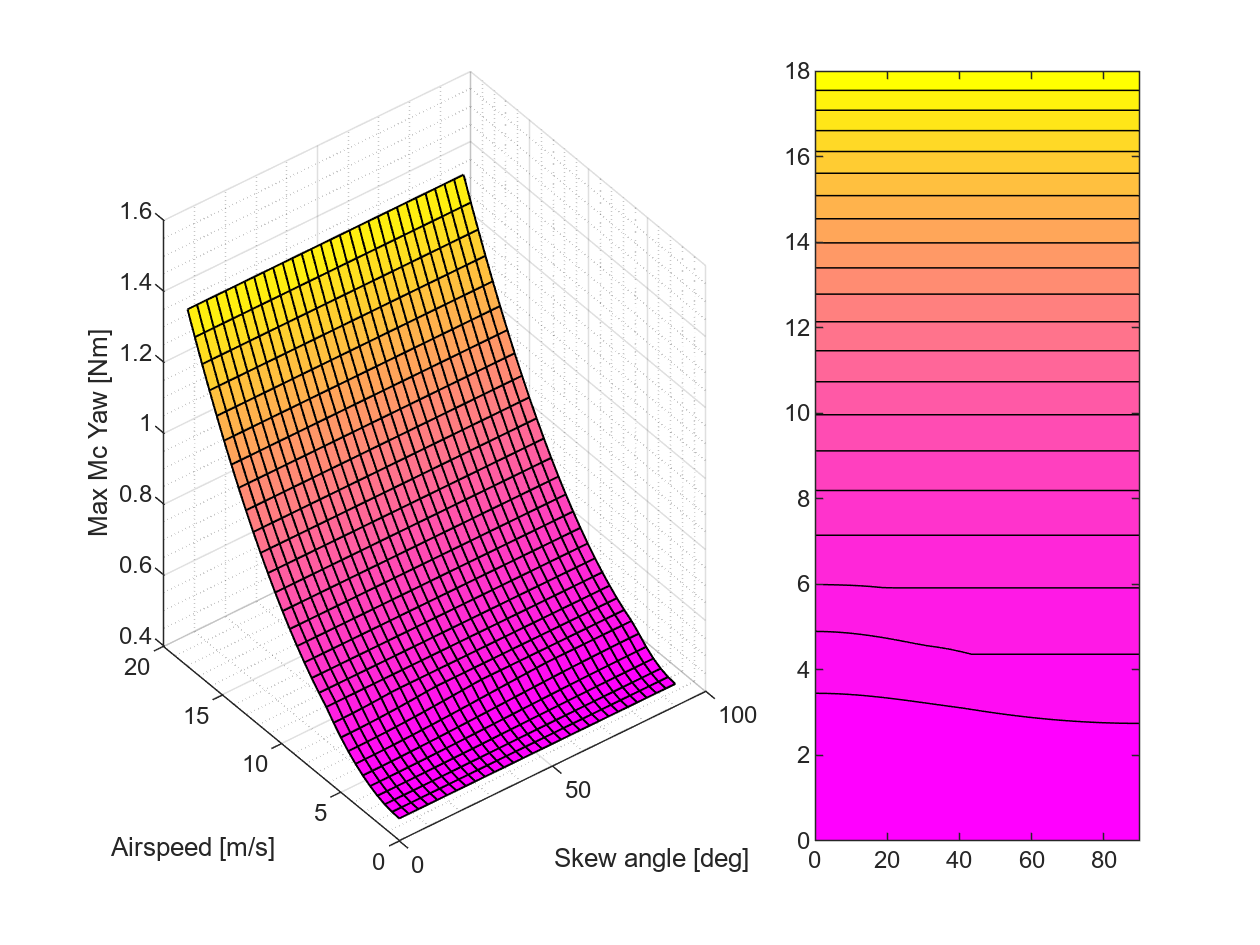

figure(12)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,M_c_yaw)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Max Mc Yaw [Nm]')
nexttile([1,2])
contourf(rad2deg(L),V,M_c_yaw,20)

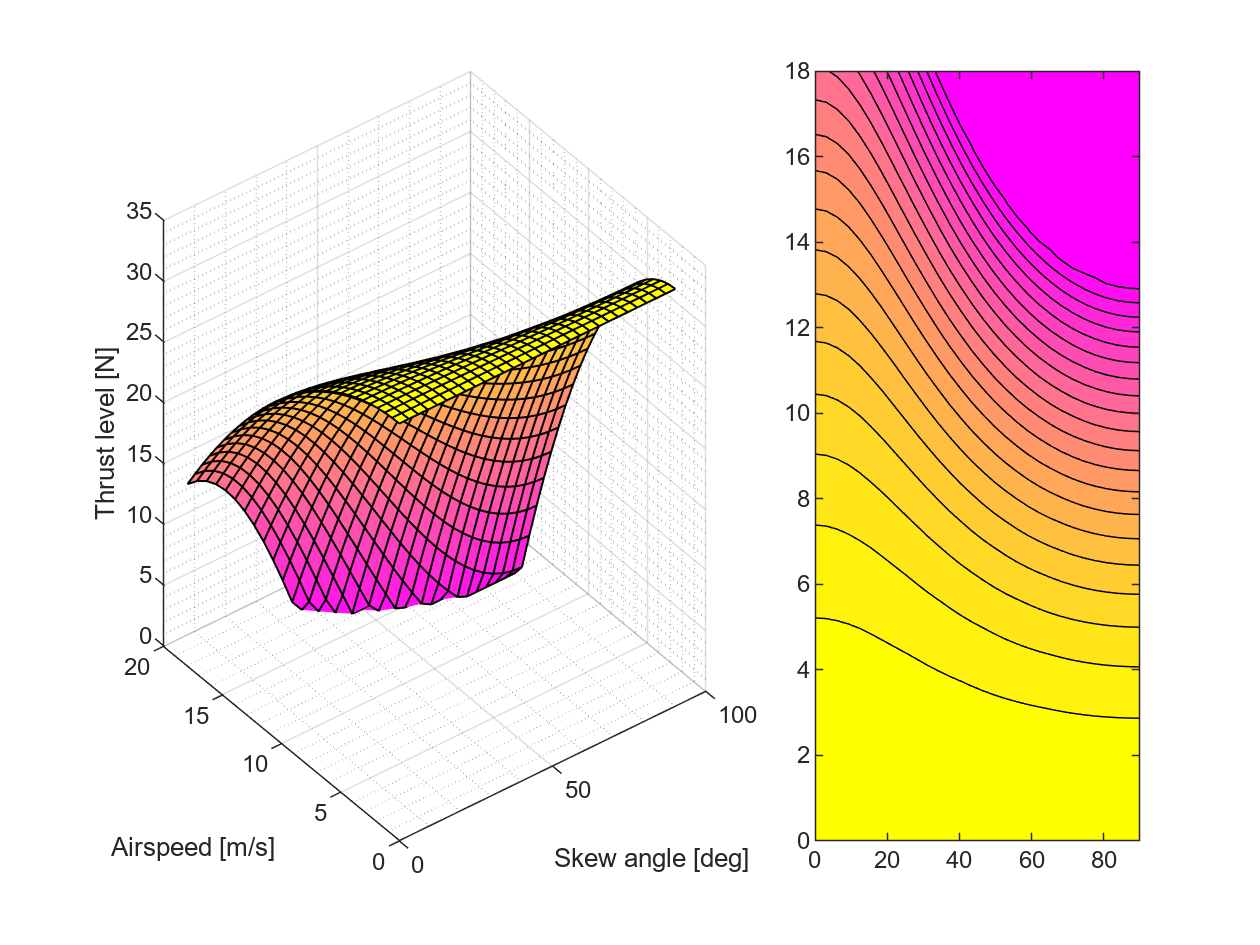

figure(13)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,Thrust_surf)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Thrust level [N]')
nexttile([1,2])
contourf(rad2deg(L),V,Thrust_surf,20)

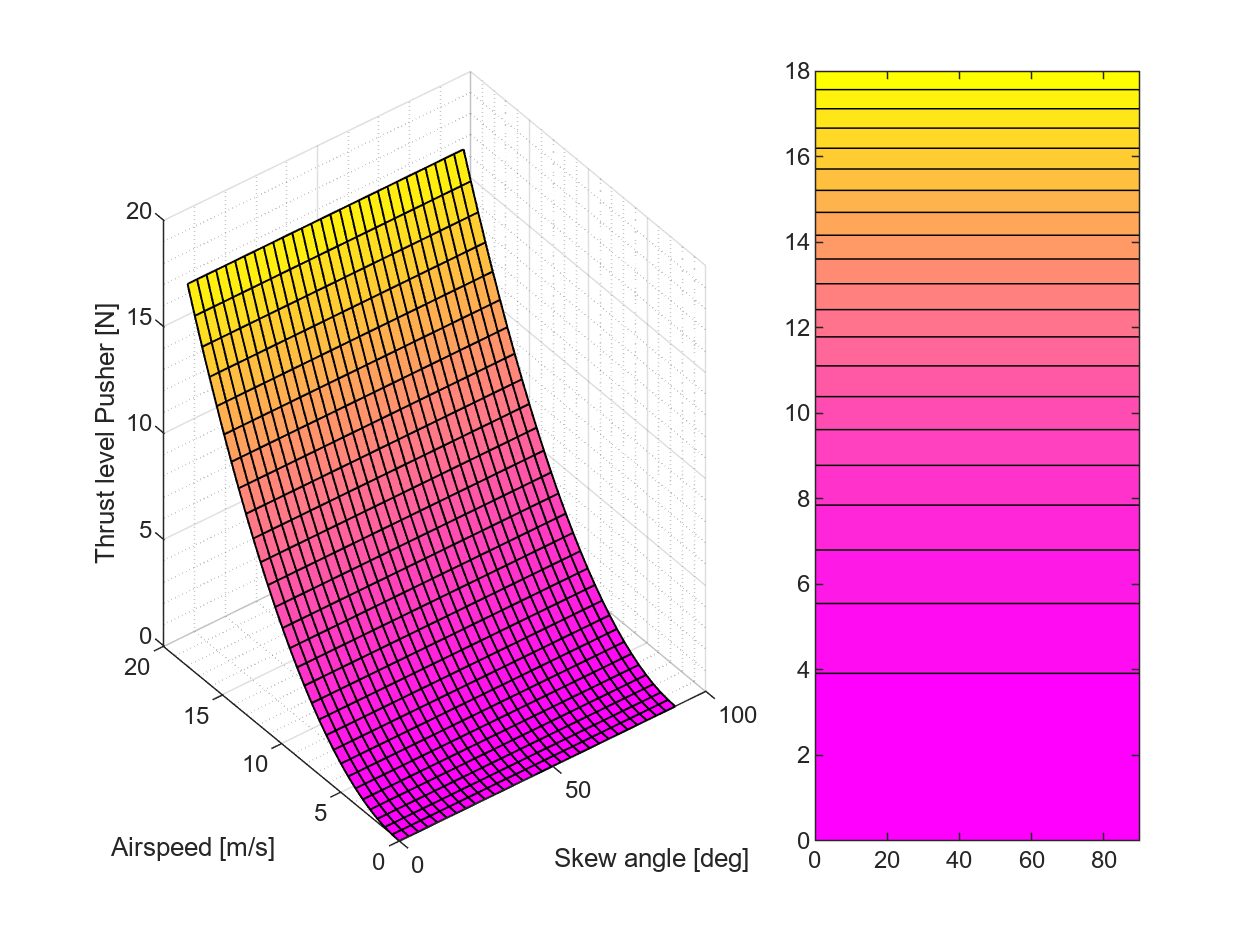

max_speed = 17 ; %[m/s]
T_bx_max  = 16 ; %[N]
Thrust_bx_surf = T_bx_max/(max_speed^2)*V.^2;
figure(14)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,Thrust_bx_surf)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Thrust level Pusher [N]')
nexttile([1,2])
contourf(rad2deg(L),V,Thrust_bx_surf,20)

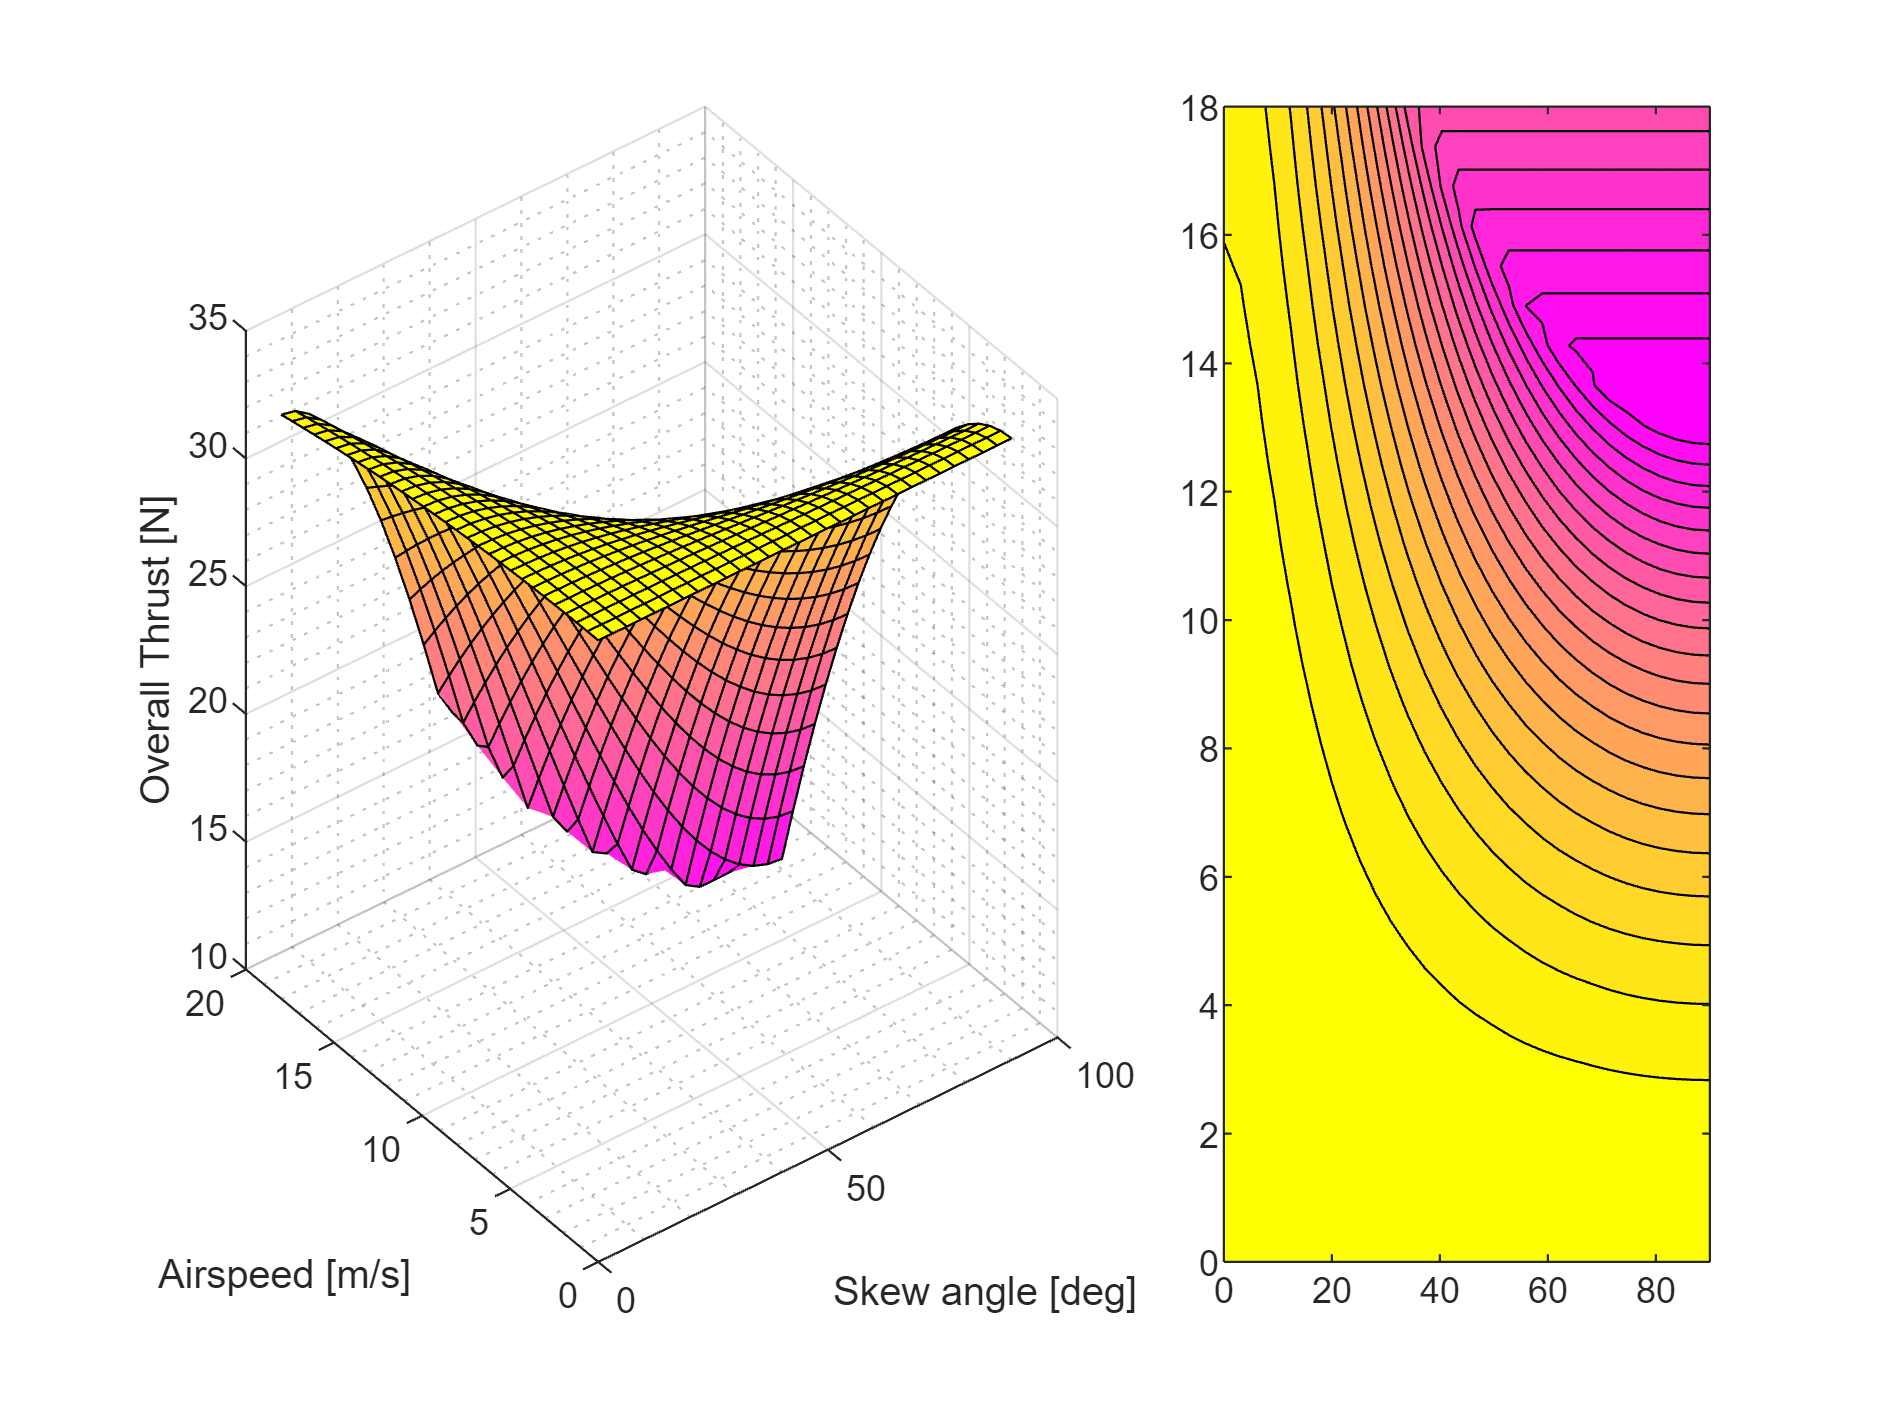

figure(15)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,Thrust_bx_surf+Thrust_surf)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Overall Thrust [N]')
nexttile([1,2])
contourf(rad2deg(L),V,Thrust_bx_surf+Thrust_surf,20)

In order t derive a desired skew set point per considered airspeed we have to fuse the found surfaces in a way that reflects the desired behaviour of the drone. 

**Step 1:**

Normalize the surfaces so that a fair comparison can be carried according to :


$$S_{\textrm{norm}} =\frac{S}{\max \left(||S||\right)}$$


**Step 2:**

Define a fourth surface to represent the power cost of a certain airspeed skew combination. This surface is defined by


$$T_{\textrm{tot}} \left(\Lambda ,v\right)=T_{\textrm{qud}} +T_{\textrm{push}} =\max \left(\textrm{mass}\;g-L\left(\Lambda ,v\right),0\right)+a*v^2$$



$$S_T \left(\Lambda ,v\right)=\frac{1}{T_{\textrm{tot}} \left(\Lambda ,v\right)}$$


**Step 3:**

Fuse the surfaces toghether using weighting factors


$$M_{c_{\textrm{tot}} } =\left\lbrack \begin{array}{cccc}
\gamma_{\phi }  & \gamma_{\theta }  & \gamma_{\psi }  & \gamma_T 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
M_{c_{\phi } } \\
M_{c_{\theta } } \\
M_{c_{\psi } } \\
S_T 
\end{array}\right\rbrack$$


[L,V] = meshgrid(lambda_q,v_q);
gamma = [2,3,1,4];
lift_num = matlabFunction(lift);
lift_surf = 1./(Thrust_bx_surf+Thrust_surf); 
lift_off = lift_surf./max(lift_surf(:));
M_c_roll_norm = M_c_roll./ max(M_c_roll(:));
M_c_pitch_norm = M_c_pitch./ max(M_c_pitch(:));
M_c_yaw_norm = M_c_yaw./ max(M_c_yaw(:));
surf_tot = gamma(1)*M_c_roll_norm + gamma(2)*M_c_pitch_norm + gamma(3)*M_c_yaw_norm+gamma(4)*lift_off;
[Zmax,idx_Z] = max(surf_tot,[],2);
peak = find(diff(Zmax)<0,1,'first');

The result is a surface which represent a fusion between the orignal control moment surfaces and the power consuption surface. Now we can evaluate what is the maximum of this surface at each query airspeed and find at which $\Lambda$it occurs. Connecting these maxima will result in a strategy to maximize control across a range of considered airspeeds. 

On the other hand, it can be noticed that sometimes moving inbetween maxima involves first a decrease in control moment. This behaviour is undesired because it would lead to commanded states which actually momentarly decrease control authority. Therefore there is the need to reach the maximum control authority state while always following an ever increasing path.

 In order to reach the maximum point we can then follow a gradient ascend algorithm following the maximum gradient. The most basic example of it uses a constant learning rate $\alpha$ which is followed along the direction of the calculated gradient of the surface.


$$X_{n+1} =X_n +\alpha \;\nabla S_{\textrm{tot}} \left(X_n \right)$$



$$\nabla S_{\mathrm{tot}} \left(X_n \right)=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial \Lambda }S_{\mathrm{tot}} \left(X\right)\\
\frac{\partial }{\partial v}S_{\mathrm{tot}} \left(X\right)
\end{array}\right\rbrack |X=X_n$$


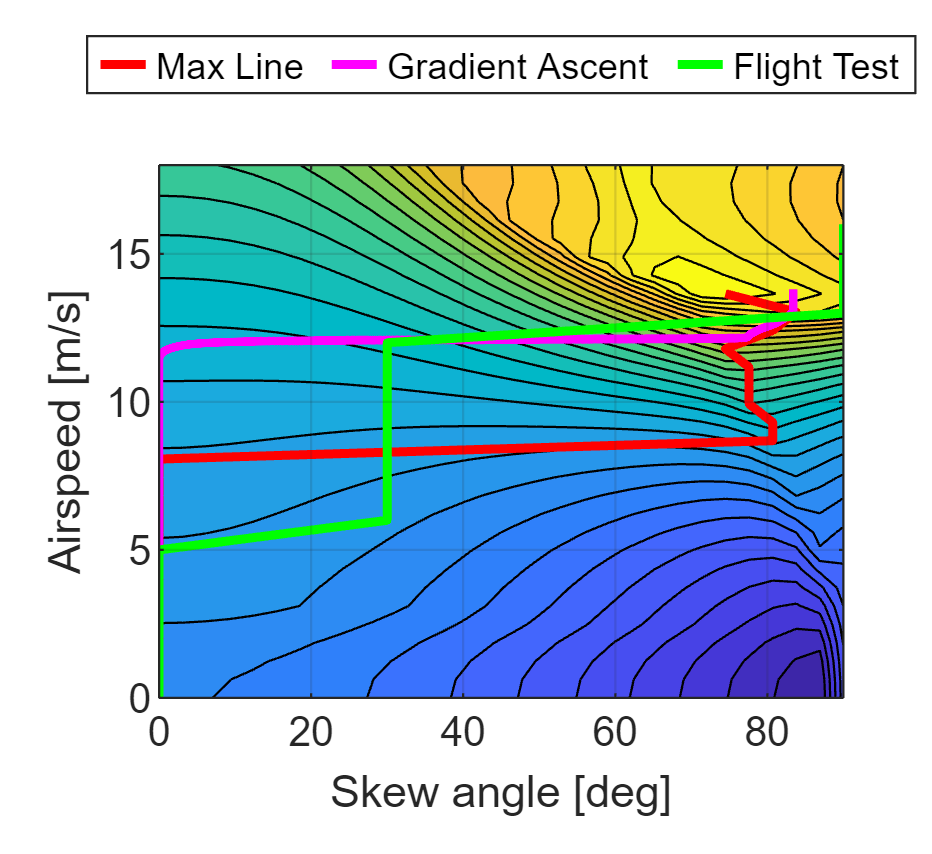

folder = fullfile(pwd,'plots_save');
%[fx,fy] = gradient(surf_tot,mean(diff(v_q)),mean(diff(lambda_q)));
[fx,fy] = gradient(surf_tot,rad2deg(mean(diff(lambda_q))),mean(diff(v_q)));
iters = 10000;
n0 = zeros(iters,2);
n0(1,:) = [0 0];
v0 = zeros(iters,1);
v0(1) = interp2(L,V,surf_tot,n0(1,1),n0(1,2));
alpha = 3;%0.55; Settings: Low,High : 0.03,0.03  simple 3
a_des = 0.08;%      Settings: Low,High : 0.01,0.08
I_zz_rp = 2 * (0.20684*0.33813^2+0.15476*0.365^2); %[kgm^2]
L = rad2deg(L);
alpha = 8;
iters = 20000;
for idx =2:iters
    dFdx = interp2(L,V,fx,n0(idx-1,1),n0(idx-1,2)); % partial derivative with respect to Lambda
    dFdy = interp2(L,V,fy,n0(idx-1,1),n0(idx-1,2)); % partial derivative with respect to Airspeed
    
    % Increase skew when it brings advantages. E.G. positive gradient
    if dFdx > 0 
        delta = alpha.*[dFdx,dFdy/10000]; 
    else
        delta = alpha.*[0,dFdy]; 
        delta(2)= min(0.002,abs(delta(2)))/sign(delta(2)); % Uncomment for fixed airspeed ascent
    end
    % if saddle point stop
    if delta == [0,0]
        %delta = [rad2deg(mean(diff(lambda_q))),mean(diff(v_q))];
        break
    end
    % Update ascent 
    n0(idx,:)= n0(idx-1,:) + delta;
    % Do not excceed limits of ascent
    n0(idx,:)= max([0.01,0.01],n0(idx,:));
    n0(idx,:)= min([rad2deg(lambda_q(end)-0.01),v_q(end)-0.01],n0(idx,:));
    v0(idx,1) = interp2(L,V,surf_tot,n0(idx,1),n0(idx,2));
end

f=figure(200);
clf
t = tiledlayout(1,1);
%% Un comment to have also 3D plot%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%t = tiledlayout(1,2);
% nexttile
% surf(L,V,surf_tot)
% grid on
% grid minor
% hold on 
% peak_surf = max(surf_tot,[],2);
% plot3(rad2deg(lambda_q(idx_Z(1:peak))),v_q(1:peak),peak_surf(1:peak),'-r','LineWidth',2)
% plot3(n0(:,1),n0(:,2),v0,'-m','LineWidth',2);
% %plot([0,0,0,0,0,0,30,30,30,30,30,30,90,90,90,90,90],[0,1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16],'-g','LineWidth',2)
% xlabel('Skew angle [deg]')
% ylabel('Airspeed [m/s]')
% zlabel('S_{tot}')%('Interp surface [(Nm)^3]')
% ax = gca;
% %ax.Children = ax.Children([3 1 2]);
% ax.SortMethod='depth';\
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
nexttile
contourf(L,V,surf_tot,30)
grid on
hold on 
plot(rad2deg(lambda_q(idx_Z(1:peak))),v_q(1:peak),'-r','LineWidth',2);
plot(n0(:,1),n0(:,2),'-m','LineWidth',2);
plot([0,0,0,0,0,0,30,30,30,30,30,30,30,90,90,90,90],[0,1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16],'-g','LineWidth',2)
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
lgd = legend("","Max Line","Gradient Ascent","Flight Test",'NumColumns',3);
lgd.Layout.Tile = 'north';
lgd.ItemTokenSize = [10,8];
f.Units = 'inches';
f.OuterPosition = [0 0 3 3];
ax = gca;
%ax.Children = ax.Children([4 1 3 2]);
ax.SortMethod='ChildOrder';
exportgraphics(f,fullfile(folder,strcat('skew_plan','.pdf')),'ContentType','vector')